#### Overview:

This live script is intended to generate and present the results for Lab3: Gait Analysis. It uses the function ProcessLab3Data.m to generate the respective results for the three trials. ProcessLab3Data.m takes a .mat file name string as an input and returns all the data needed to present for lab.

#### Process data and run calculations:

clear;
[slowStepStats, slowAngles, slowMoments, slowGRF, slowStartStance] = ProcessLab3Data('DataSlow.mat');
[normStepStats, normAngles, normMoments, normGRF, normStartStance] = ProcessLab3Data('DataNormal.mat');
[fastStepStats, fastAngles, fastMoments, fastGRF, fastStartStance] = ProcessLab3Data('DataFast.mat');

slowAngles = slowAngles(slowGRF(:,3)>slowStartStance,:);
normAngles = normAngles(normGRF(:,3)>slowStartStance,:);
fastAngles = fastAngles(fastGRF(:,3)>slowStartStance,:);

slowMoments = slowMoments(slowGRF(:,3)>slowStartStance,:);
normMoments = normMoments(normGRF(:,3)>slowStartStance,:);
fastMoments = fastMoments(fastGRF(:,3)>slowStartStance,:);

#### Generate Table of Step Stats

columnNames = {'Gait Speed [m/s]', 'Step Length [m]', 'Cadence [steps/min]'};
rowNames = {'Slow', 'Normal', 'Fast'};
data = [slowStepStats; normStepStats; fastStepStats];
dataTable = table(data(:, 1), data(:, 2), data(:, 3), 'VariableNames', columnNames, 'RowNames', rowNames)

dataTable = 3×3 table
              Gait Speed [m/s]    Step Length [m]    Cadence [steps/min]
              ________________    _______________    ___________________

    Slow           1.0078             0.70338              85.967       
    Normal         1.4015             0.72228              116.43       
    Fast           1.9516             0.84326              138.86       


#### Plot Joint Angles During Stance Phase (order: foot, shank, thigh)

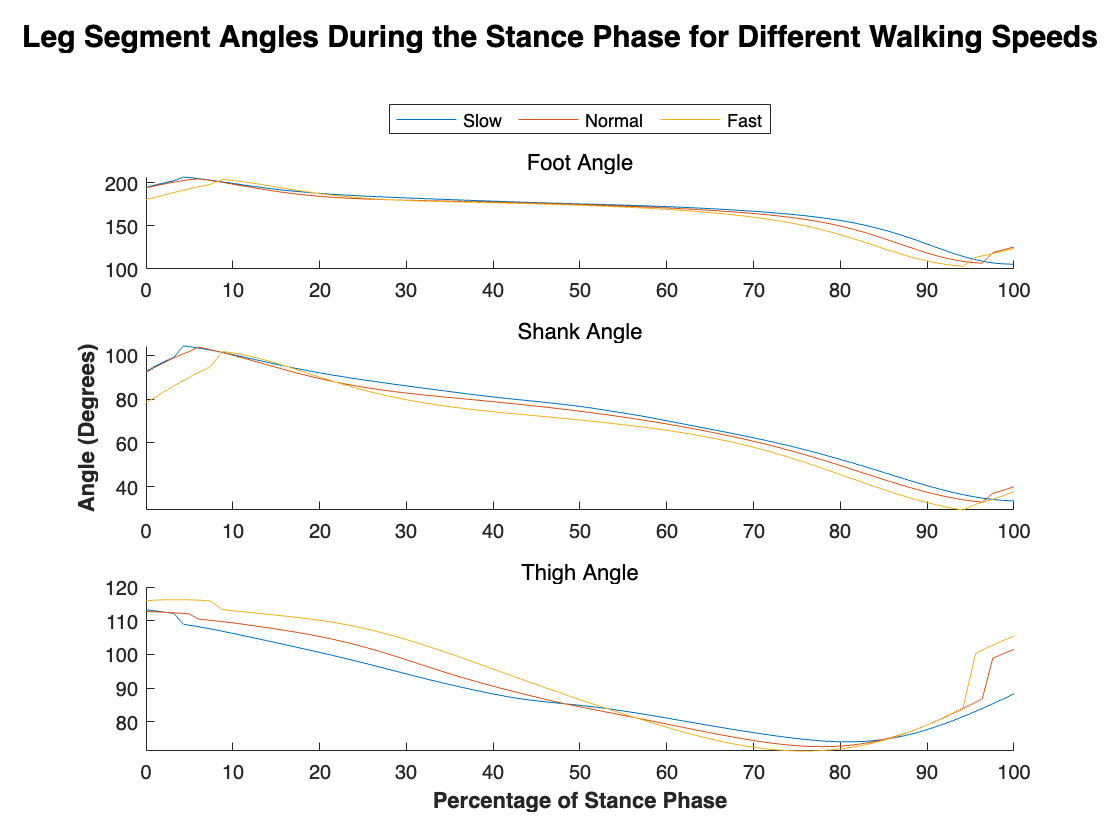

figure
titles = {'Foot Angle','Shank Angle','Thigh Angle'};
for i = 1:3
    subplot(3,1,i)
    hold on
    plot(linspace(0,100,length(slowAngles)), rad2deg(slowAngles(:,i)))
    plot(linspace(0,100,length(normAngles)),rad2deg(normAngles(:,i)))
    plot(linspace(0,100,length(fastAngles)),rad2deg(fastAngles(:,i)))
    title(titles(i),'FontWeight','normal')
    if i == 2
        ylabel('Angle (Degrees)','FontWeight','bold')
    end
    hold off
    if i == 1
        legend('Slow','Normal','Fast','Orientation','horizontal','Location','northoutside')
    end
end
sgtitle('Leg Segment Angles During the Stance Phase for Different Walking Speeds','FontWeight','bold')
xlabel('Percentage of Stance Phase','FontWeight','bold')

#### Plot Joint Moments During Stance Phase (order: ankle, knee, hip)

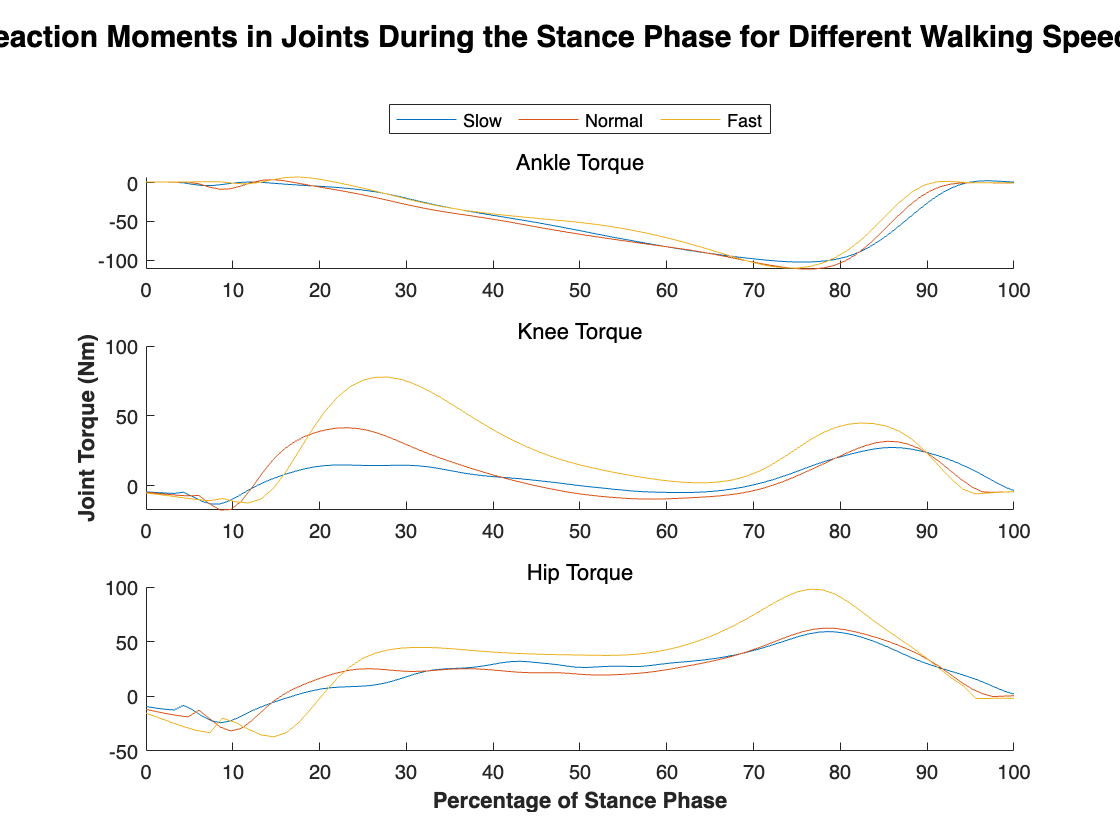

figure
titles = {'Ankle Torque','Knee Torque','Hip Torque'};
for i = 1:3
    subplot(3,1,i)
    
    hold on
    plot(linspace(0, 100, length(slowMoments)), slowMoments(:,i))
    plot(linspace(0, 100, length(normMoments)), normMoments(:,i))
    plot(linspace(0, 100, length(fastMoments)), fastMoments(:,i))
    title(titles(i),'FontWeight','normal')
    if i == 2
        ylabel('Joint Torque (Nm)','FontWeight','bold')
    end
    if i == 1
        legend('Slow','Normal','Fast','Orientation','horizontal','Location','northoutside')
    end


    hold off
end
    
sgtitle('Reaction Moments in Joints During the Stance Phase for Different Walking Speeds','FontWeight','bold')
xlabel('Percentage of Stance Phase','FontWeight','bold')